clc; clear all;

# LiPo

%% Environment
env = struct();
env.g = 9.8065;
env.dens = 1.225;

%% Battery 
Bat = struct();
Bat.Cp = 4.398;               % Capacity in A*h
Bat.Cps = Bat.Cp * 3600;    % Capacity in A*s
Bat.k = 1.03;
Bat.Q0 = 1.;                % SoC
Bat.ncell = 6;
Bat.Vcell = 4.2;
Bat.Voc = Bat.Vcell * Bat.ncell;
Bat.Crate = 100;
Bat.Imax = Bat.Crate * Bat.Cp;
Bat.Rp_cell = 1.8e-3;
Bat.Rp = Bat.Rp_cell * Bat.ncell;
Bat.Cpol_cell = 50;                    % 500 F ... 3000 F
Bat.Cpol = Bat.Cpol_cell / Bat.ncell;
Bat.R0_cell = 2.89e-3;                     % 2e-3 ... 8e-3
Bat.Ro = Bat.R0_cell * Bat.ncell;
Bat.Cbat = 5e-2; % battery capacity 1e-2 ... 1 F
Bat.mass = 0.341;   % weight
Bat.size.length = 110;
Bat.size.height = 48;
Bat.size.width = 34;
%% ESC
ESC = struct();
ESC.Imax = Bat.Imax;
ESC.Vmax = Bat.Voc;
ESC.Vmin =0;
ESC.R = 5e-3;
Kv = 1200;
ESC.Ke = 60 / (2 * pi * Kv);    %
ESC.I_idle = 0.7;               % 
%% Motor
motor = struct();
motor.Kv = Kv;                          % RPM per voltage
motor.Kt = 30 / (pi * motor.Kv);        % frequency 
motor.Ke = 30 / (pi * motor.Kv);        %
motor.Imax = ESC.Imax;      % maximum motor current
motor.R = 2e-2;             % motor resistance
motor.maxRPM = motor.Kv * Bat.Voc;  % maximum RPM
motor.maxFreq = motor.maxRPM * pi /30;  % frquency, ras/s
motor.Jm = 9.5e-7;
motor.B = 1e-12;    % B * w, motor internal resistance to rotation dependent on frequency
motor.Lm = 7.5e-6;   % 20 µH (option for engine start dynamic if needed)
motor.Tmax = 2.0;   % max thrust [kg]
% Fan
fan = struct();
fan.Ct = 2.5e-6;
fan.Cload = 5.19e-8;   % fan resistance coefficient
PX4.THR_MDL_FAC  = 0.76;
PX4.THR_VLT_COMP_MAX = 1.3;
PX4.BAT1_V_CHARGED  = 4.05 * Bat.ncell;
PX4.MPC_THR_HOVER = 0.45252;
PX4.MPC_THR_MIN = 0.1; 
PX4.MPC_THR_MAX = 0.9;

PX4.MPC_Z_VEL_MAX_UP = 12.0;
PX4.MPC_Z_VEL_MAX_DN = -12.0;

PX4.MPC_ACC_UP_MAX = 10;
PX4.MPC_ACC_DOWN_MAX = -10;
PX4.MOT_SLEW_MAX = 20.; % shouldn't be used for position -> attitude and rate only

copter.mass = 3.5 / 4; 
% Simulation parameters
Ts = 0.01;          % Samoling time
Tf = 90;            % simulation duration
Tend = Tf + 10;

## LookUp Table

LookUp.SoC = flip([1.00	0.95	0.9	0.85	0.8	0.75	0.7	0.65	0.6	0.55	0.5	0.45	0.4	0.35	0.3	0.25	0.2	0.15	0.1	0.05	0]);
LookUp.Volts = flip([25.20	24.89808307	24.63642173	24.39488818	24.09297125	23.77092652	23.58977636	23.3884984	23.20734824	23.04632588	22.92555911	22.80479233	22.70415335	22.62364217	22.54313099	22.4827476	22.38210863	22.26134185	22.14057508	22.0600639	21.47635783]);
coeffs = [ 152.975524, -621.192127, 1018.494797, -867.398284,  413.388249, ...
    -107.742204,   14.463508,   22.144734];

x0 = [0;0];
Az = [0 1;
    0 0];
Bz = [0; 1/copter.mass];
Gz = [0; -env.g];

# Outdated paramters

g = 9.8065;
% Battery
Cp = 2.2;
I_idle = 0.7;
I_max_disc = 75 * Cp;
k = 1.03;
Q0 = 1.;
Cps = Cp * 3600;
R0_cell = 2e-3;     % 2e-3 ... 8e-3
Cpol_cell = 2e3;    % 500 F ... 3000 F
Rp_cell = 2.4e-3;   % 5e-3 ... 15e-3
ncell = 6;
Ro = R0_cell * ncell;
Rp = Rp_cell * ncell;
Cpol = Cpol_cell / ncell;
Vcell = 4.2;
Vbat = 22.2;
Voc = ncell * Vcell;
Cbat = 5e-2; % battery capacity 1e-2 ... 1 F
% Motor
Kv = 2000;
Kt = 60 / (2 * pi * Kv);
I_motor_max = 120;
Rm = 0.02;                  % Motor resistance
B = 1e-12;                  % 
Lm = 3e-6;                  % inductance 1e-6 ... 5e-6 H
% ESC
Ke = 60 / (2 * pi * Kv);
RPM_max = ncell * Vcell * Kv;
Jm = 2e-7;
Ct = 1.23e-6;
Cload = 5e-8;   % fan resistance coefficient
Resc = 5e-3;


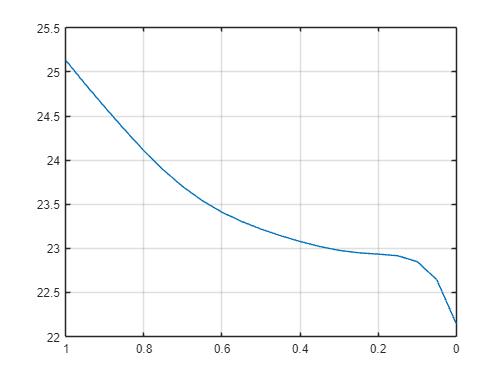

figure;
plot(LookUp.SoC, polyval(coeffs, LookUp.SoC)); grid;
set(gca, 'XDir', 'reverse');

## ODE

I = 60.;
ode_discharge = @(t,x, I) (-I^k / Cps);
ode_voltage_sag = @(t,x) (-x / (Rp * Cpol) + I / Cpol);

## Solving

Ts = 0.1; Tf = 1 * 90;
T = 0:Ts:Tf;
[t, z] = ode45(ode_discharge, T, Q0, args=I);
[tv, zv] = ode45(ode_voltage_sag, T, 0);

## Results

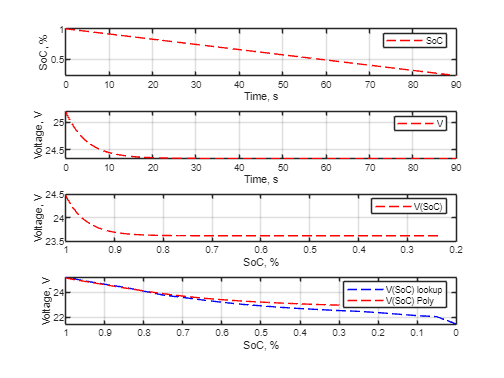

figure;
subplot(4,1,1);
plot(t, z, 'r--'); grid;
xlabel('Time, s');
ylabel('SoC, %');
legend({'SoC'});
subplot(4,1,2);
plot(t, Voc - zv, 'r--'); grid;
xlabel('Time, s');
ylabel('Voltage, V');
legend({'V'});

subplot(4,1,3);
plot(z, Voc - zv -I * Ro, 'r--'); grid;
xlabel('SoC, %'); set(gca, 'XDir', 'reverse');
ylabel('Voltage, V');
legend({'V(SoC)'});

y_poly = polyval(coeffs, z);
subplot(4,1,4);
plot(LookUp.SoC, LookUp.Volts, 'b--'); hold on;
plot(z, y_poly, 'r--'); grid;
xlabel('SoC, %'); 

set(gca, 'XDir', 'reverse');
ylabel('Voltage, V');
legend({'V(SoC) lookup','V(SoC) Poly'});

# ESC

## Parameters

Rm = 0.2; % 0.02 ... 0.06;

## Solving

throttle = 0.65;
omega = throttle * RPM_max * pi / 30;
V_bat = Voc - zv;
V_eff = throttle * V_bat;
I_motor = (V_eff - Ke * omega) / Rm;

## Average values

Tmotor_max = Kt * I_motor_max

Tmotor_max = 0.5730

w_max = Kv * Vcell*ncell * pi / 30

w_max = 5.2779e+03

Tmax = Ct * w_max ^2

Tmax = 34.2628

Tload = Cload * w_max^2

Tload = 1.3928

Vcell*ncell / Ke

ans = 5.2779e+03

Ct1 = 3.5 * g / w_max ^2

Ct1 = 1.2322e-06

w_dot = Kt * I_max_disc / Jm

w_dot = 3.9391e+06